close all;
clc;
robot = loadrobot("universalUR5e");
robot.DataFormat = 'row';

ur5e = exampleHelperAddGripper(robot);

Home Position

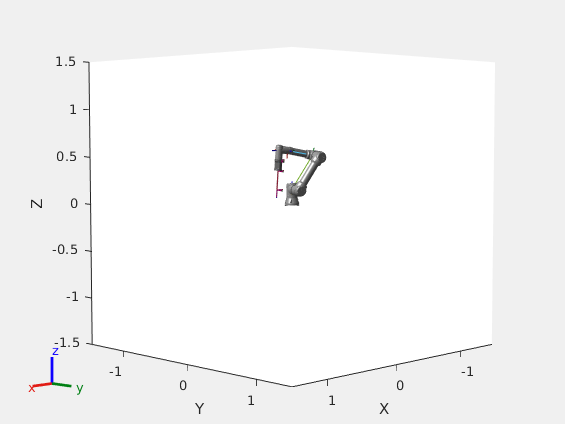

homePosition = deg2rad([-15 -126 113 -80 -91 76]);

% Set home position of each joint
ur5e.Bodies{1, 3}.Joint.HomePosition = homePosition(1);
ur5e.Bodies{1, 4}.Joint.HomePosition = homePosition(2);
ur5e.Bodies{1, 5}.Joint.HomePosition = homePosition(3);
ur5e.Bodies{1, 6}.Joint.HomePosition = homePosition(4);
ur5e.Bodies{1, 7}.Joint.HomePosition = homePosition(5);
ur5e.Bodies{1, 8}.Joint.HomePosition = homePosition(6);

% Show robot at home position
f1 = figure;
show(ur5e,homePosition,'Frames','on','PreservePlot',false,'Collisions','off','Visuals','on');
hold on

Inverse kinematic solver

% Define the target position (x, y, z) for the end-effector
goalPosition = [0.3, 0.1, 0.5]; % Replace with your target position

% Define the target orientation using Euler angles (roll, pitch, yaw) in radians
goalOrientation = eul2rotm([0, pi/4, 0], 'XYZ'); % Replace with desired orientation

% Combine the position and orientation into the transformation matrix T_06
T_06 = [goalOrientation, goalPosition'; 0, 0, 0, 1];

% Inverse kinematic solver
ik = inverseKinematics('RigidBodyTree', ur5e);
weights = [1, 1, 1, 1, 1, 1];
initialGuess = homePosition;
[theta, solutionInfo] = ik('tool0', T_06, weights, initialGuess);

% Display the solution
disp('MATLAB IK solution:');

MATLAB IK solution:


disp(theta);

   -0.1505   -5.8408   -2.2742   -2.1009   -1.4645    1.6777



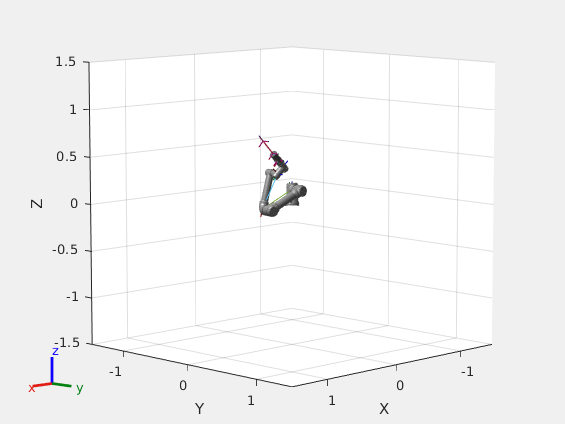

show(ur5e, theta, 'Frames', 'on', 'PreservePlot', false);

% Define waypoints as columns for X, Y, Z positions
waypoints = [0.7, 0.2, 0.6;  % X positions
             0.0, 0.7, 0.3;  % Y positions
             0.4, 0.8, 0.0]; % Z positions


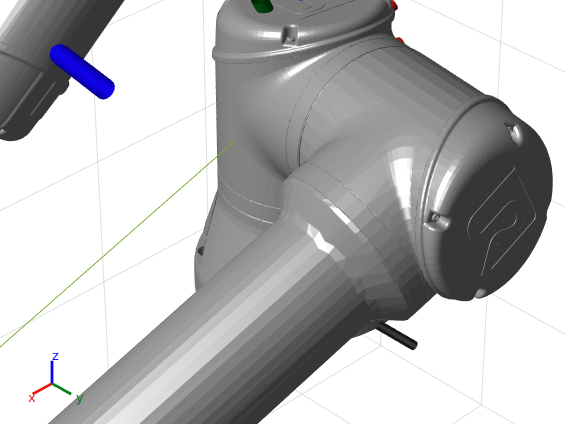

% Show the robot in the solved pose
show(ur5e, theta, 'Frames', 'on', 'PreservePlot', true);

% Plot the waypoints
plot3(waypoints(1,:), waypoints(2,:), waypoints(3,:), 'ro');  % 'ro' for red circles

% Set axis limits to make sure everything fits in the plot
axis([-1, 1, -1, 1, 0, 1]);
view(3);  % 3D view 
axis equal;  % Equal scaling on all axes

% Optional: Adjust camera position if needed
campos([1, 1, 1]);  % Set camera position to view the plot better


% exampleHelperPlotWaypoints(waypoints)
% trajectory=cscvn(waypoints')
% fnplt(trajectory,'r',2)
